# Частотная модуляция 

# Основы

**Для запуска скриптов необходимо корневую папку репозитория сделать рабочей папкой Matlab!**

### 1. Введение

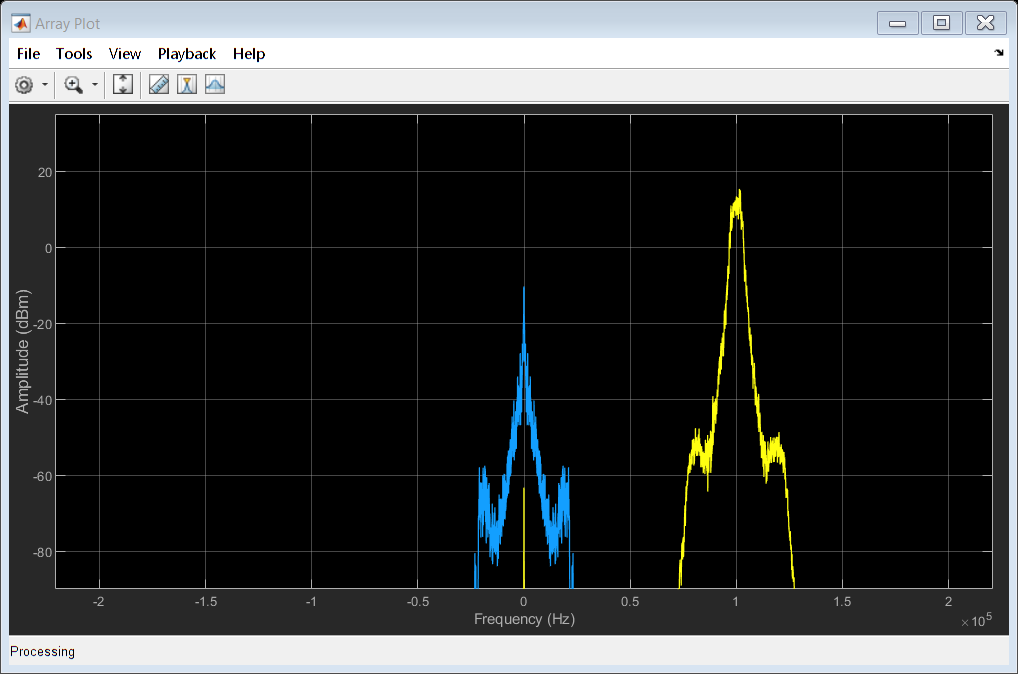

clc; clear; close all;

SignalFrameSize = 10000;          % количество отсчетов чм-сигнала, получаемых за один раз
FramesNumber = 500;               % число обрабатываемых пачек данных
AudioAmp = 1;                     % коэффициент усиления аудиосигнала
RateRatio = 10;                   % коэффициент увеличения частоты дискретизации
ModIndex = '02';   % индекс модуляции

% имя считываемого файла
SignalFileName = sprintf('wav/Audio_FM_ModIdx_%s.wav', ModIndex);

% объект для считываения отсчетов аудиофайла
AudioReader = dsp.AudioFileReader(...
    SignalFileName, ...
    'SamplesPerFrame',SignalFrameSize...
    );

% дополнительные расчеты
SignalFs = AudioReader.SampleRate;              % получаем частоту дискретизации модулированного сигнала
AudioFs = SignalFs / RateRatio;                 % частота дискретизации аудиосообщения

% задержка 
DelayBlock = dsp.Delay;

% дециматор 
DownSampler = dsp.SampleRateConverter(...
    'Bandwidth', 30e3, ...
    'InputSampleRate', SignalFs, ...
    'OutputSampleRate', AudioFs ...
    );

% объект для вычисления спектра
SpecEstimator = dsp.SpectrumEstimator(...
    'PowerUnits','dBm',...
    'FrequencyRange','centered',...
    'SampleRate',SignalFs);

% объект для отрисовки графиков
Plotter = dsp.ArrayPlot(...
    'PlotType','Line', ...
    'XOffset', -SignalFs/2, ...
    'YLimits', [-90, 35], ...
    'XLabel', 'Frequency (Hz)', ...
    'YLabel', 'Amplitude (dBm)', ...
    'ChannelNames', {'FM Signal', 'Audio Signal'}, ...
    'SampleIncrement', SignalFs/SignalFrameSize ...
    );

Message = [];

% запуск симуляции
for i = 1:FramesNumber
    % считывание отсчетов ЧМ-сигнала и выделение синфазного канала
    FmSignal = AudioReader();
    FmSignal = FmSignal(:,1) + 1j*FmSignal(:,2);
 
    % вычисление производной с помощью первой разности
    FmSignalDelayed = DelayBlock(FmSignal);
    DerivativeSignal = FmSignal - FmSignalDelayed;

    % вычисление модуля
    AbsSignal = abs(DerivativeSignal);
    
    % удаляем постоянную составляющую
    AbsSignal = AbsSignal - mean(AbsSignal);
    
    % понижение частоты дискретизации
    Message = [Message; AudioAmp * DownSampler(AbsSignal)];

    % вычисление спектров
    SpectrumData = SpecEstimator([FmSignal AbsSignal]);

    % вывод результатов на график
    Plotter(SpectrumData)

    % задержка в 0.1 секунды для лучшей визуализации
    pause(0.01)
end

% проигрывание полученного сообщения
sound(Message, AudioFs);

clc; clear; close all;
addpath('matlab/demodulation');

Fc = 106.2e6;                % частота несущей в Hz
SignalFs = 1.2e6;            % частота дискретизации RTL-SDR
AudioFs = 48e3;              % частота дискретизации демодулированного аудиосигнала
SignalFrameSize = 512*25;    % количество отсчетов чм-сигнала, получаемых за один раз
FcShift = 75e3;              % частота сдвига после фильтрации
AudioAmp = 0.2;              % коэффициент усиления аудиосигнала
AudioDownsampleRatio = 10;   % коэффициент увеличения частоты дискретизации

SDRRTL = comm.SDRRTLReceiver(...
    'RadioAddress', '0',...
    'CenterFrequency', Fc,...
    'EnableTunerAGC', true,...
    'SampleRate', SignalFs, ...
    'SamplesPerFrame', SignalFrameSize,...
    'OutputDataType', 'double' ...
);

% расчет коэффициентов и создание фильтра нижних частот
Fpass = 110e3;
Fstop = 160e3;
H = Audio_Lowpass_FIR_Coeff(SignalFs, Fpass, Fstop);
LowpassFIR = dsp.FIRFilter(H.Numerator);

% генератор для сдвига сигнала по частоте
Mixer = dsp.SineWave(...
    'SampleRate', SignalFs,...
    'SamplesPerFrame', SignalFrameSize,...
    'Frequency', FcShift,...
    'ComplexOutput', true, ...
    'Amplitude', 1);

% задержка на один отсчет
DelayBlock = dsp.Delay;

% дециматор 
DownSampler = dsp.SampleRateConverter(...
    'Bandwidth', 30e3, ...
    'StopbandAttenuation', 80, ...
    'InputSampleRate', SignalFs, ...
    'OutputSampleRate', AudioFs ...
    );

% объект для вычисления спектра
SpecEstimator = dsp.SpectrumEstimator(...
    'PowerUnits','dBm',...
    'FrequencyRange','centered',...
    'SampleRate',SignalFs);

% объект для отрисовки графиков
Plotter = dsp.ArrayPlot(...
    'PlotType','Line', ...
    'XOffset', -SignalFs/2, ...
    'YLimits', [-90, 35], ...
    'XLabel', 'Frequency (Hz)', ...
    'YLabel', 'Amplitude (dBm)', ...
    'ChannelNames', {'FM Signal'}, ...
    'SampleIncrement', SignalFs/SignalFrameSize ...
    );

% воспроизведение аудио сигнала
AudioSink = audioDeviceWriter(AudioFs);

% запуск симуляции
while(true)
    % получение отсчетов сигнала
    FmSignalData = SDRRTL();
    
    % вычисление спектров и вывод результатов на график
    SpectrumData = SpecEstimator(FmSignalData);
    Plotter(SpectrumData);
    
    % удаление постоянной составляющей
    FmSignalData = FmSignalData - mean(FmSignalData);
    
    % фильтрация
    FilteredData = LowpassFIR(FmSignalData);
    
    % сдвиг сигнала по частоте
    MixedData = FilteredData .* Mixer();
    
    % вычисление производной с помощью первой разности
    MixedDataDelayed = DelayBlock(MixedData);
    DerivativeSignal = MixedData - MixedDataDelayed;
    
    % вычисление модуля
    AbsSignal = abs(DerivativeSignal);
    
    % удаляем постоянную составляющую
    AbsSignal = AbsSignal - mean(AbsSignal);
    
    % уменьшение частоты дискретизации
    AudioData = DownSampler(AbsSignal);
   
    % проигрывание данных
    AudioSink(AudioData * AudioAmp);
  
end

### Литература:

- B. P. Lathi Modern Digital and Analog Communication Systems

- R. Stewart, K. Barlee, D. Atkinson, L. Crockett Software Defined Radio using MATLAB® & Simulink and the RTL-SDR